L = readtable("LULU Exel.xlsx")

L = 27×7 table
         Date              Open              High              Low              Close            AdjClose         Volume  
    ______________    ______________    ______________    ______________    ______________    ______________    __________

    {'2024-01-22'}    {'483.000000'}    {'484.309998'}    {'468.160004'}    {'478.029999'}    {'478.029999'}    5.4403e+06
    {'2024-01-29'}    {'478.029999'}    {'491.299988'}    {'451.350006'}    {'462.399994'}    {'462.399994'}    7.9171e+06
    {'2024-02-05'}    {'458.410004'}    {'476.619995'}    {'450.059998'}    {'470.239990'}    {'470.239990'}    6.5707e+06
    {'2024-02-12'}    {'473.279999'}    {'478.000000'}    {'445.529999'}    {'449.600006'}    {'449.600006'}    5.3922e+06
    {'20

open = L.Open;
open = cell2mat(open)

open = 27×10 char array
    '483.000000'
    '478.029999'
    '458.410004'
    '473.279999'
    '445.769989'
    '461.059998'
    '458.630005'
    '461.529999'
    '465.920013'
    '405.089996'
    '393.549988'
    '358.609985'
    '340.989990'
    '354.679993'
    '357.890015'
    '357.000000'
    '354.369995'
    '334.209991'
    '304.000000'
    '311.260010'
    '314.660004'
    '304.279999'
    '312.290009'
    '300.730011'
    '300.420013'
    '289.500000'
    '281.779999'


date = L.Date

date = 27×1 cell array
    {'2024-01-22'}
    {'2024-01-29'}
    {'2024-02-05'}
    {'2024-02-12'}
    {'2024-02-19'}
    {'2024-02-26'}
    {'2024-03-04'}
    {'2024-03-11'}
    {'2024-03-18'}
    {'2024-03-25'}
    {'2024-04-01'}
    {'2024-04-08'}
    {'2024-04-15'}
    {'2024-04-22'}
    {'2024-04-29'}
    {'2024-05-06'}
    {'2024-05-13'}
    {'2024-05-20'}
    {'2024-05-27'}
    {'2024-06-03'}
    {'2024-06-10'}
    {'2024-06-17'}
    {'2024-06-24'}
    {'2024-07-01'}
    {'2024-07-08'}
    {'2024-07-15'}
    {'2024-07-22'}


close = L.Close;
close = cell2mat(close)

close = 27×10 char array
    '478.029999'
    '462.399994'
    '470.239990'
    '449.600006'
    '457.890015'
    '458.500000'
    '460.390015'
    '464.940002'
    '403.190002'
    '390.649994'
    '356.869995'
    '336.130005'
    '352.470001'
    '364.700012'
    '355.149994'
    '352.959991'
    '334.950012'
    '303.010010'
    '311.989990'
    '317.859985'
    '306.010010'
    '311.820007'
    '298.700012'
    '298.140015'
    '291.059998'
    '280.239990'
    '286.000000'


for i = 1:size(open,1)
   Open(i) = str2double(open(i,:));
 end

for i = 1:size(close,1)
   Close(i) = str2double(close(i,:));
 end

for i = 1:size(date,1)
   Date(i) = datetime(date(i,:),'InputFormat','uuuu-MM-dd');
end

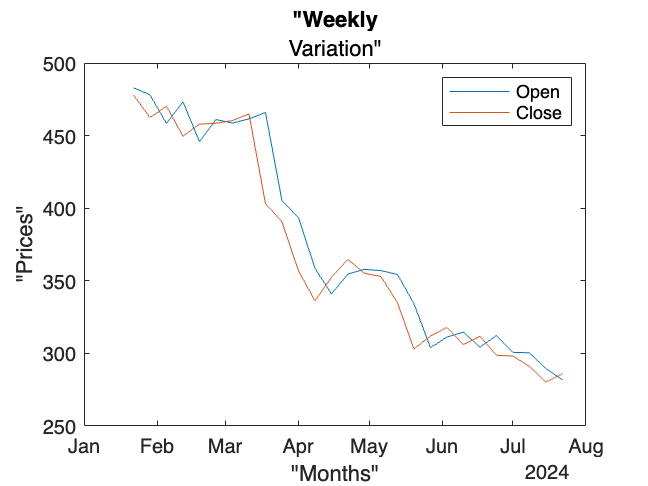

plot(Date,Open)
hold on
plot (Date,Close)
legend ("Open","Close")
title "Weekly Variation"
xlabel "Months"
ylabel "Prices"
hold off

time = 1:27;